# Ecuaciones no lineales

Dada una función $f\left(x\right)$ tal que $f:\Re \to \Re$ es de interés calcular al menos una raíz de la ecuación $f\left(x\right)=0$. Es decir, se necesita calcular un $\hat{x} \in \Re$ tal que $f\left(\hat{x} \right)=0$

### Método de bisección

Si sabemos que una función es continua en el intervalo $\left\lbrack a,b\right\rbrack$ y existe un cambio de signo entonces


$$f\left(a\right)*f\left(b\right)<0$$


de esta manera, se puede garantizar que existe al menos un valor $c\in \left\lbrack a,b\right\rbrack$ tal que $f\left(c\right)=0$

Calcular una raíz de la función  $f\left(x\right)=x^3 +e^x$ en el intervalo  $\left\lbrack -2,0\right\rbrack$

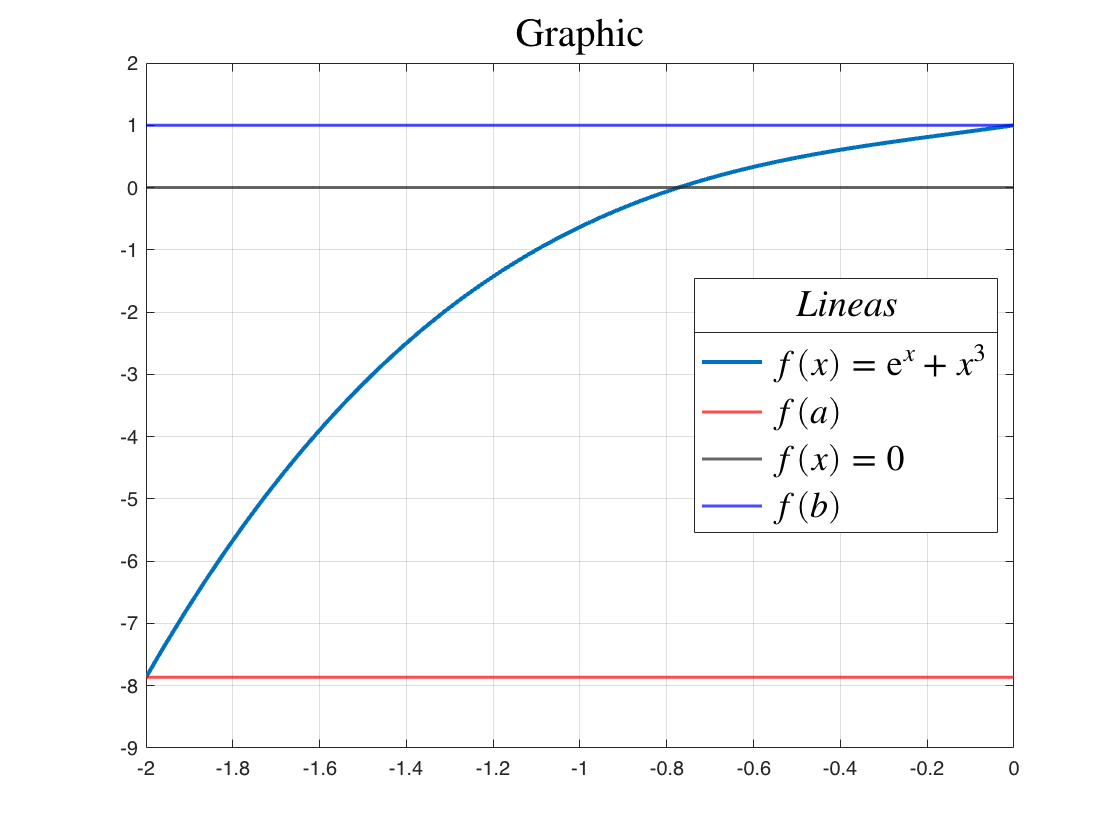

f = @(x) (x.^3 + exp(x));
a = -2;
b = 0;

fplot(f, 'LineWidth', 2);
title('Graphic', 'Interpreter','latex', 'FontSize', 20)
grid on;
axis([a b, -9 2])

yline(f(a), Color='r', LineWidth=1.5);
yline(0, LineWidth=1.5);
yline(f(b), Color='b', LineWidth=1.5);

lgnd = legend(["$f(x) = {\mathrm{e}}^x +x^3$", "$f(a)$", "$f(x)=0$","$f(b)$"], 'Interpreter', 'latex', 'Location','east', 'FontSize', 18);
title(lgnd, '$Lines$', 'Interpreter','latex', 'FontSize', 19)
hold off;

Tol = 1e-5;

[~, c] = BiseccionTOL(f, a, b, Tol);

    i        a           b           c           f(a)           f(b)          f(c)          error   
    __    ________    ________    ________    ___________    __________    ___________    __________

     0          -2           0          -1        -7.8647             1       -0.63212             1
     1          -1           0        -0.5       -0.63212             1        0.48153           0.5
     2          -1        -0.5       -0.75       -0.63212       0.48153       0.050492          0.25
     3          -1       -0.75      -0.875       -0.63212      0.050492       -0.25306         0.125
     4      -0.875       -0.75     -0.8125       -0.25306      0.050492       -0.09263        0.0625
     5     -0.8125  

Entonces, $c$ es el valor aproximado de la raíz de la función $f\left(x\right)$ tal que $f\left(c\right)\approx 0$ usando una tolerancia de ${10}^{-5}$.

c = vpa(c)

$$c = -0.77288055419921875$$

fc = vpa(f(c))

$$fc = 0.000005420082277008064410759272510189$$

Se puede verificar que $f\left(c\right)\approx 0$.

### Método del punto fijo

En esta parte se considera un método para determinar la solución de una ecuación $f\left(x\right)=0$ que se puede expresar, para alguna función $g$, en la forma $g\left(x\right)=x$. A una solución de esta ecuación se le llama **Punto Fijo** de la función $g$.

Sean $a,b\in \Re$ tales que $a\;<b$ y sea $g:\left\lbrack a,b\right\rbrack \to \Re$ una función continua en $\left\lbrack a,b\right\rbrack$ y derivable en $\left\langle a,b\right\rangle$ que satisface:

- $\left|\frac{\mathrm{d}}{\textrm{d}x}g\left(x\right)\right|<1$ para cualquier $x\in \left\langle a,b\right\rangle$

- $g\left(x\right)\in \left\lbrack a,b\right\rbrack$ para cualquier $x\in \left\lbrack a,b\right\rbrack$

Entonces existe un único $\rho \in \left\langle a,b\right\rangle$ tal que $g\left(\rho \right)=\rho$.  Además, si $x^{\left(0\right)}$ es algún punto en el intervalo $\left\lbrack a,b\right\rbrack$ y se construye la sucesión $\left\lbrace x^{\left(k\right)} \right\rbrace$ en la forma $x^{\left(k+1\right)} =g\left(x^{\left(k\right)} \right)$ entonces la sucesión $\left\lbrace x^{\left(k\right)} \right\rbrace$ converge al punto fijo $\rho$ de la función $g$ tal que $g\left(\rho \right)=\rho$ y $f\left(\rho \right)=0$.

Calcular una raíz de la función $f\left(x\right)=2e^{x^2 } -5x$ con un $x^{\left(0\right)} =0$


$$f\left(x\right)=2e^{x^2 } -5x=0$$
 


$$-5x=-2e^{x^2 }$$
 


$$x=\frac{2}{5}e^{x^2 } =g\left(x\right)$$


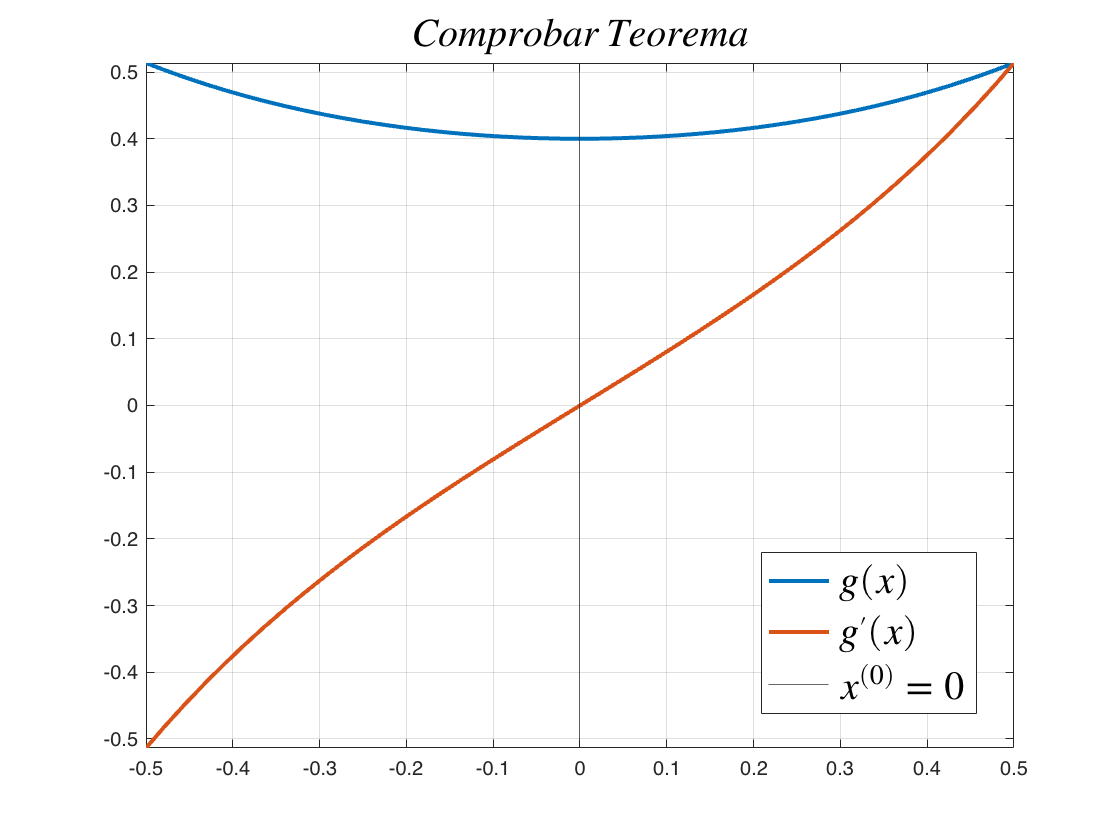

syms x;

f = @(x) (2.*exp(x.^2) - 5.*x);
g = @(x) (2/5.*exp(x.^2));
x0 = 0;

a = x0-0.5;
b = x0+0.5;

fplot(g, [a b], LineWidth=2);

hold on; grid on;
fplot(diff(g, x), [a b], LineWidth=2);
title("$Comprobar\,Teorema$", 'Interpreter','latex', 'FontSize',20)
xline(x0)
legend({"$g(x)$" "$g'(x)$" '$x^{(0)}=0$'}, 'Interpreter', 'latex', 'Location','best', 'FontSize',20)
hold off; 

Como $\left|\frac{\mathrm{d}}{\mathrm{d}x}g\left(x\right)\right|<1$ para cualquier $x\in \left\langle -0\ldotp 5,0\ldotp 5\right\rangle$ y $g\left(x\right)\in \left\lbrack -0\ldotp 5,0\ldotp 5\right\rbrack$ para cualquier $x\in \left\lbrack -0\ldotp 5,0\ldotp 5\right\rbrack$ entonces se garantiza la convergencia del método del **Punto Fijo**.

Tol = 1e-5;

[~, rho] = PuntoFijoTOL(g, x0, Tol);

    i      x[i]      g(x[i])      error   
    __    _______    _______    __________

     0          0        0.4           NaN
     1        0.4     0.4694             1
     2     0.4694     0.4986       0.14786
     3     0.4986    0.51289      0.058556
     4    0.51289    0.52036      0.027866
     5    0.52036    0.52439      0.014353
     6    0.52439    0.52661     0.0076872
     7    0.52661    0.52783     0.0042027
     8    0.52783    0.52852     0.0023233
     9    0.52852     0.5289     0.0012922
    10     0.5289    0.52911     0.0007212
    11    0.52911    0.52923    0.00040326
    12    0.52923     0.5293    0.00022572
    13     0.5293    0.52933    0.00012642
    14    0.52933    0.52935    7.0826e-05
    15    0.52935    0.52937    3.9688e-05
    16    0.52937    0.52937    2.2242e-05
    17    0.52937    0.52938    1.2465e-05
   

rho = vpa(rho)

$$rho = 0.52937675441301079715117339219432$$

g_rho = vpa(g(rho))

$$g\_rho = 0.52937882729689486967744663632348$$

f_rho = f(rho)

$$f\_rho = 0.000010364419420362631366220645806461$$

Se puede verificar que $g\left(\rho \right)\approx \rho$ y $f\left(\rho \right)\approx 0$ con una tolerancia de ${10}^{-5}$.